# 2.1

## 1

a)

experiencias_a = rand(2,1e6) < 0.5;
resultados_a = sum(experiencias_a) >= 1;
prob_a = sum(resultados_a)/1e6;

b)

prob_b = 3/4;

c)

experiencias_c = rand(2,1e6);
experiencias_c = experiencias_c < 0.5;
columns  = sum(experiencias_c)>= 1;
soma = experiencias_c(:,columns);
resultados_c = sum(soma) == 2;
prob_c = sum(resultados_c)/size(resultados_c,2);

d)

experiencias_d = rand(2,1e6);
experiencias_d(1,:) = zeros(1,1e6);
experiencias_d = experiencias_d < 0.5;
resultados_d = sum(experiencias_d) == 2;
prob_d = sum(resultados_d)/1e6;

e)

experiencias_e = rand(5,1e6);
experiencias_e = experiencias_e < 0.5;
columns_e  = sum(experiencias_e)>= 1;
soma_e = experiencias_e(:,columns_e);
resultados_e = sum(soma_e) == 2;
prob_e = sum(resultados_e)/size(resultados_e,2);

f)

experiencias_f = rand(5,1e6);
experiencias_f = experiencias_f < 0.5;
columns_f  = sum(experiencias_f)>= 1;
soma_f = experiencias_f(:,columns_f);
resultados_f = sum(soma_f) >= 2;
prob_f = sum(resultados_f)/size(resultados_f,2);

## 2

a)

N_experiencias_2a = 1e6;
n_alvos_2a = 100;
n_dardos_2a = 20;
experiencias_2a = randi(n_alvos_2a,n_dardos_2a,N_experiencias_2a);
hits_2a = 0;
for i = 1:N_experiencias_2a
    if size(unique(experiencias_2a(:,i)),1) == n_dardos_2a
        hits_2a = hits_2a + 1;
    end
end
prob_2a = hits_2a/N_experiencias_2a

prob_2a = 0.1299

b)

N_experiencias_2b = 1e6;
n_alvos_2b = 100;
n_dardos_2b = 20;
experiencias_2b = randi(n_alvos_2b,n_dardos_2b,N_experiencias_2b);
hits_2b = 0;
for i = 1:N_experiencias_2b
    if size(unique(experiencias_2b(:,i)),1) < n_dardos_2b
        hits_2b = hits_2b + 1;
    end
end
prob_2b = hits_2b/N_experiencias_2b

prob_2b = 0.8700

c)

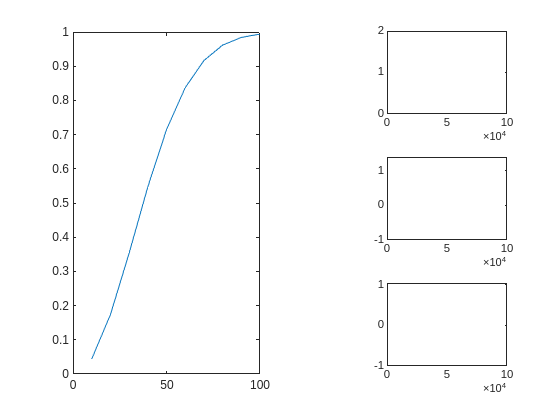

N_experiencias_2c1 = 1e5;
n_alvos_2c1 = 1000;
probs_2c1 = [];
for n_dardos_2c1 = 10:10:100
    experiencias_2c1 = randi(n_alvos_2c1,n_dardos_2c1,N_experiencias_2c1);
    hits_2c1 = 0;
    for i = 1:N_experiencias_2c1
        if size(unique(experiencias_2c1(:,i)),1) < n_dardos_2c1
            hits_2c1 = hits_2c1 + 1;
        end
    end
    prob_2c1 = hits_2c1/N_experiencias_2c1;
    probs_2c1 = [probs_2c1 prob_2c1];
end
subplot(1,2,1)
plot(10:10:100,probs_2c1)

N_experiencias_2c2 = 1e5;
n_alvos_2c2 = 100000;
probs_2c2 = [];
for n_dardos_2c2 = 10:10:100
    experiencias_2c2 = randi(n_alvos_2c2,n_dardos_2c2,N_experiencias_2c2);
    hits_2c2 = 0;
    for i = 1:N_experiencias_2c2
        if size(unique(experiencias_2c2(:,i)),1) < n_dardos_2c2
            hits_2c2 = hits_2c2 + 1;
        end
    end
    prob_2c2 = hits_2c2/N_experiencias_2c2;
    probs_2c2 = [probs_2c2 prob_2c2];
end
subplot(1,2,2)
plot(10:10:100,probs_2c2)

d)

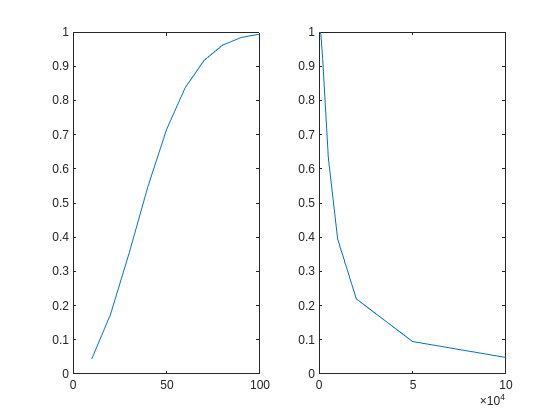

N_experiencias_2d = 1e5;
n_alvos_2d = [200, 500, 1000, 2000, 5000, 10000,20000, 50000 ,100000];
n_dardos_2d = 100;
probs_2d = [];
for j = n_alvos_2d
    experiencias_2d = randi(j,n_dardos_2d,N_experiencias_2d);
    hits_2d = 0;
    for i = 1:N_experiencias_2d
        if size(unique(experiencias_2d(:,i)),1) < n_dardos_2d
            hits_2d = hits_2d + 1;
        end
    end
    prob_2d = hits_2d/N_experiencias_2d;
    probs_2d = [probs_2d prob_2d];
end

plot(n_alvos_2d,probs_2d)

## 3

a)

N_experiencias_3a = 1e5;
n_keys_3a = 10;
tamanho_array_3a = 1000;
experiencias_3a = randi(tamanho_array_3a,n_keys_3a,N_experiencias_3a);
hits_3a = 0;
for i = 1:N_experiencias_3a
    if size(unique(experiencias_3a(:,i)),1) < n_keys_3a
        hits_3a = hits_3a + 1;
    end
end
prob_3a = hits_3a/N_experiencias_3a;

b)

N_experiencias_3b = 1e5;
tamanho_array_3b = 1000;
probs_3b = [];
for n_keys_3b = 1:100:1000
    experiencias_3b = randi(tamanho_array_3b,n_keys_3b,N_experiencias_3b);
    hits_3b = 0;
    for i = 1:N_experiencias_3b
        if size(unique(experiencias_3b(:,i)),1) < n_keys_3b
            hits_3b = hits_3b + 1;
        end
    end
    prob_3b = hits_3b/N_experiencias_3b;
    probs_3b = [probs_3b prob_3b];
end
plot(1:100:1000,probs_3b)

c)

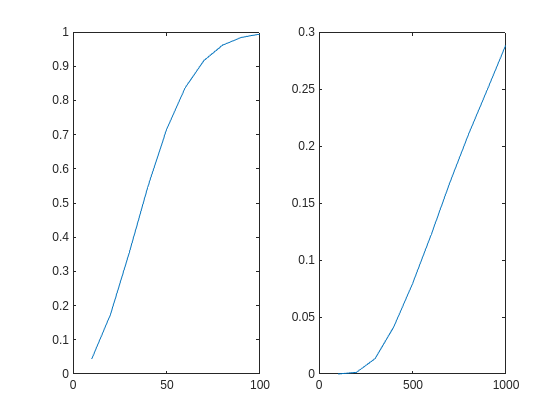

N_experiencias_3c = 1e5;
n_keys_3c = 50;
probs_3c = [];
for tamanho_array_3c = 100:100:1000
    experiencias_3c = randi(tamanho_array_3c,n_keys_3c,N_experiencias_3c);
    hits_3c = 0;
    for i = 1:N_experiencias_3c
        if size(unique(experiencias_3c(:,i)),1) == n_keys_3c
            hits_3c = hits_3c + 1;
        end
    end
    prob_3c = hits_3c/N_experiencias_3c;
    probs_3c = [probs_3c prob_3c];
end
plot(100:100:1000,probs_3c)

# 2.2

## 1

a)

A – a soma dos dois valores é igual a 9

N_experiencias_22 = 1e5; 
lancamentos_1a = randi(6,2,N_experiencias_22);
resultados_1a = sum(lancamentos_1a) == 9;
prob_1a = sum(resultados_1a)/N_experiencias_22;

B – o segundo valor é par

lancamentos_1b = randi(6,2,N_experiencias_22);
resultados_1b = rem(lancamentos_1b(2,:),2) == 0;
prob_1b = sum(resultados_1b)/N_experiencias_22;

C – pelo menos um dos valores é igual a 5

lancamentos_1c = randi(6,2,N_experiencias_22);
resultados_1c = lancamentos_1c(1,:) == 5 | lancamentos_1c(2,:) == 5;
prob_1c = sum(sum(resultados_1c))/N_experiencias_22;

D – nenhum dos valores é igual a 1

lancamentos_1d = randi(6,2,N_experiencias_22);
resultados_1d = lancamentos_1d(1,:) > 1 & lancamentos_1d(2,:) > 1;
prob_1d = sum(sum(resultados_1d))/N_experiencias_22;

b)

prob_22b_calc = prob_1a .* prob_1b;
lancamentos_22b = randi(6,2,N_experiencias_22);
resultados_22b = sum(lancamentos_22b) == 9 & rem(lancamentos_22b(2,:),2) == 0;
prob_22b = sum(resultados_22b)/N_experiencias_22;
prob_22b == prob_22b_calc;

c)

prob_22c_calc = prob_1c .* prob_1d;
lancamentos_22c = randi(6,2,N_experiencias_22);
resultados_22c = lancamentos_22c(1,:) == 5 | lancamentos_22c(2,:) == 5 & lancamentos_22c(1,:) > 1 & lancamentos_22c(2,:) > 1;
prob_22c = sum(resultados_22c)/N_experiencias_22;
prob_22c == prob_22c_calc

ans = logical
   0


# 2.3?

## 1

a)

N_experiencias_22 = 1e5;
erro_andre = 0.01;
erro_bruno = 0.02;
erro_carlos = 0.005;

probabilidade_andre = 0.2;
probabilidade_bruno = 0.3;
probabilidade_carlos = 0.5;

erro_total = erro_andre*probabilidade_andre + erro_bruno*probabilidade_bruno + erro_carlos * probabilidade_carlos;

probCarlos = (erro_carlos*probabilidade_carlos)/erro_total;

probCarlos = 0.2381

b)

probAndre = (erro_andre*probabilidade_andre)/erro_total;

probAndre = 0.1905

probBruno = (erro_bruno*probabilidade_bruno)/erro_total;

probBruno = 0.5714

O programa é mais provável de ser do Bruno.

## 2

P[“sequência incluir a palavra um” | “sequência inclui palavra dois”] = P[“sequência incluir a palavra um” e “sequência inclui palavra dois”]/P[ “sequência inclui palavra dois”]

P[“sequência incluir a palavra um” e “sequência inclui palavra dois”] equivale ás sequências "um" "dois" e "dois" "um" 

P[ “sequência inclui palavra dois”] equivale ás sequências "um" "dois", "dois" "dois", "tres" "dois", "dois" "um" e "dois" "tres"

Logo P[“sequência incluir a palavra um” | “sequência inclui palavra dois”] = 2/5

# TPC

a)

N_experiencias_tpc = 1e5;
experiencias_tpc_a = randi(365,23,N_experiencias_tpc);
hits_tpc_a = 0;
for i = 1:N_experiencias_tpc
    if size(unique(experiencias_tpc_a(:,i)),1) < size(experiencias_tpc_a,1)
        hits_tpc_a = hits_tpc_a + 1;
    end
end
prob_tpc_a = hits_tpc_a/N_experiencias_tpc;

b)

experiencias_tpc_b = randi(365,41,N_experiencias_tpc);
hits_tpc_b = 0;
for i = 1:N_experiencias_tpc
    if size(unique(experiencias_tpc_b(:,i)),1) < size(experiencias_tpc_b,1)
        hits_tpc_b = hits_tpc_b + 1;
    end
end
prob_tpc_b = hits_tpc_b/N_experiencias_tpc

prob_tpc_b = 0.9049